# T5-01. Getting the auto/cross covariance function from an AR model

## Introduction

In this tutorial you will learn how to estimate the autocovariance function of a univariate random process defined by an AR model. The autocovariance function is a discrete function that depends on the lag $m$, $\gamma^{AR}[m]$.

The dataset employed in this tutorial is '*datasets/dataset_01_AR*', which includes a restricted AR model employed in Section 3.1 of** [1]**. In this tutorial, figure 5 of the mentioned reference is reproduced.

**[1]** Gallego-Castillo, C. et al., A tutorial on reproducing a predefined autocovariance function through AR models: Application to stationary homogeneous isotropic turbulence, Stochastic Environmental Research and Risk Assessment. DOI: 10.1007/s00477-021-02156-0 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

M = 30;   % máximum lag considered for gamma 


%%% Plot parameters
font_size       = 16;
figure_position = [0 0 1000 400];

Load the dataset. It consists of a restricted AR model. Check the fields required by function `get_gamma_AR`. For details related to the fields of these objects, see functions `initialise_`AR.

load dataset_01_AR AR

fprintf('j_vector is [%d, %d, %d] \n', AR.restricted_parameters.j_vector)

j_vector is [1, 2, 5] 


fprintf('a_vector is [%.1f, %.1f, %.1f] \n', AR.restricted_parameters.a_vector)

a_vector is [1.2, -0.5, 0.1] 


fprintf('b is %.1f \n',AR.restricted_parameters.b)

b is 0.5 


Initialise a `gamma` object with the fields required by function `get_gamma_AR`.

[gamma_fun] = initialise_gamma('M', M);

Compute the autocovariance function of the AR model.

[gamma_fun] = get_gamma_AR (AR, gamma_fun);

Plot the obtained autocovariance function.

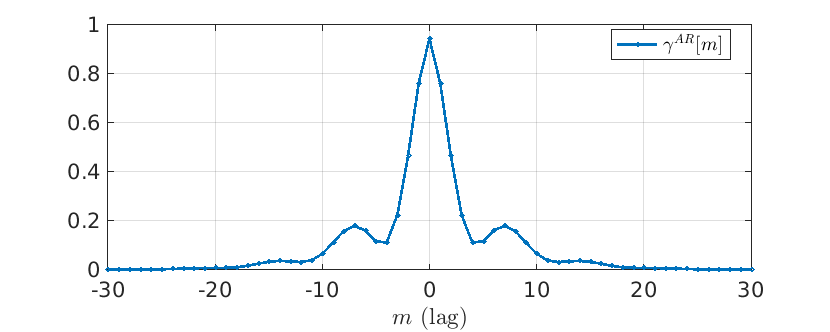

figure

x = gamma_fun.xlag_values;
y = gamma_fun.y_values;
plot(x,y,'O-','LineWidth',2,'MarkerSize',3)

grid on
legend({'$\gamma^{AR}[m]$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$m$ (lag)','Interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

Note that the *x*-axis is for lags, which are stored in field `gamma_fun.xlag_values`. The field `gamma_fun.x_values` is for cases in which the sampling time, $\Delta t$, is known, so that the autocovariance function can be represented as a function of time (or space). You can do this by adding a specific $\Delta t$ to the `gamma_fun` object through function `fun_append_gamma`, which updates `gamma_fun.x_values` (see tutorial '*T0_starting_with_mVARbox*').

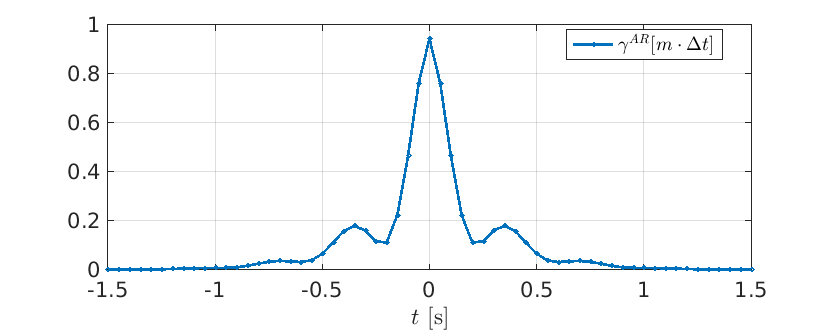

delta_t = 0.05;
gamma_fun = fun_append_gamma(gamma_fun,'delta_x',delta_t);

figure

x = gamma_fun.x_values;
y = gamma_fun.y_values;
plot(x,y,'O-','LineWidth',2,'MarkerSize',3)

grid on
legend({'$\gamma^{AR}[m\cdot\Delta t]$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$t$ [s]','Interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

A nice check consists in verifying that the integral of the autocovariance function (the discrete summatory in the lag domain multiplied by $\Delta t$) corresponds to the value fo the 2-sided PSD for zero frequency, 


$$\Delta t \cdot \sum_{m=-\infty}^{\infty}\gamma^{AR}[m] = S^{AR,2S}(f=0)$$


Note that the one-sided PSD is twice the two-sided PSD, thus,

$S^{AR,2S}(0) = 0.5 \cdot S^{AR}(0)$.

Compute the integral of the autocovariance function.

summatory_gamma_AR = delta_t * sum(gamma_fun.y_values)

summatory_gamma_AR = 0.3120

Compute the value of the 2-sided PSD at zero frequency (see tutorial '*T6_01_getting_S_from_AR*').

f_max       = 1/(2*delta_t);
f_vector    = 0;
S0 = initialise_S('ind_var','f',...
                  'x_values',f_vector, ...
                  'x_max',f_max);
S_AR = get_S_AR(AR,S0); % one-sided PSD
S_AR_2S_0 = 0.5*S_AR.y_values

S_AR_2S_0 = 0.3125

The mismatch between them is due to the fact that the computed summatory of the autocovariance function ranges from $-M$ to $M$ rather than from $-\infty$ to $\infty$. Increasing the value of the maximum lag reduces the mismatch.

## Remarks

The final check described in this tutorial stems from the Wiener-Khinchin theorem, which states that the autocovariance function and the two-sided PSD are Fourier pairs: 


$$S^{2S}(f) = \Delta t \sum_{m=-\infty}^{\infty} \gamma[m] \cdot \text{exp}(-j \, 2 \pi f  \, m  \, \Delta t),$$
   

particularised for $f=0$.